# IEEE Signal Processing Cup 2020 - Kvalifikacije

student:

Miloš Pivaš 

2015/0107

## Izveštaj

#### Definisanje problema

    Dato je 5 normalnih i 5 abnormalnih snimaka merenja.

    Zadatak je da se implementiraju modeli koji će na osnovu merenja iz .bag fajlova dati predikciju da li je snimak normal/abnormal.

    Zatim predikcije uporediti sa pravom klasom kojoj snimak pripada i na taj način odrediti tačnost modela.

#### Vizualizacija:

    Iz topic-a "/pylon_camera_node/image_raw" su izvučene slike, rotirane za 180 stepeni i sačuvane u video fajlove sa framerate-om 4fps.

    Iz izvučenih videa se vidi da snimci potiču sa neke bespilotne letilice,

    gde su normalni snimci snimljeni pri stabilnom letu bez mnogo pomeranja,

    dok su abnormalni snimljeni pri izrazito nestabilnom letu.

#### Predanaliza

    U svakom snimku ima stotinak merenja, ali zadatak nije klasifikacija merenja nego klasifikacija snimaka.

    => Ne možemo da koristimo klasičnu klasifikaciju jer nemamo labele za sama merenja.

    => Moguće rešenje: nenadgledano učimo raspodele merenja normalnih podataka, detektujemo anomalije, na osvnovu broja anomalija klasifikujemo snimak kao normalni/abnormalni.

    Usvajamo sledeće pretpostavke:

        - Normalni snimak ne sadrži abnormalna merenja.

        - Abnormalni snimak sadrži neka abnormalna merenja.

        - Obeležja su nezavisna.

    Model:

        - Usvajamo da Gauss-ovu raspodelu za merenja

        - Transformišemo podatke ako nisu Gauss-ovski

        - Kako su obeležja nezavisna, za vektor obeležja x važi: p(x) = p(x(1)) * p(x(2)) * ... * p(x(n))

        - Fitujemo parametre za Gauss-ovu raspodelu, vektore mu i sigma, na trening skupu.

        - Klasifikujemo merenje x kao abnormalno ako je p(x) < Epsilon

        - Klasifikujemo snimak kao abnormalan ako sadrži više od Alfa (uzastopnih?) abnormalnih merenja

    Pošto podatke treba podeliti na trening, CV i test skupove, imamo:

        Trening skup:   3 normalna snimka, 0 abnormalnih    za fitovanje raspodela

        CV skup:        1 normalni snimak, 2 abnormalna     za podešavanje parametra Epsilon i Alfa

        Test skup:      1 normalni snimak, 3 abnormalna     za konačnu evaluaciju modela

    Za evaluaciju klasifikacije koristimo F_1 skor.

    Pošto je u test skupu normalna klasa u manjini, proglašavamo nju za pozitivnu klasu.

        TP - #true positive,    FP - #false positive,   FN - #false negative

    precision: P = TP/(TP + FP),    recall: R = TP/(TP + FN),   F_1 skor: F_1 = 2*P*R/(P + R)

#### Analiza merenja

    Na osnovu izvučenih videa, izabrana su sledeća merenja kao relevantna za analizu:

        "/mavros/global_position/local"

        "/mavros/imu/data"

        "/mavros/imu/mag"

        "/mavros/global_position/compass_hdg"

    Došlo se do zaključka da je su oscilacije određenih merenja kod abnormalnih snimaka značajno veće nego kod normalnih.

    To znači da izvodi tih veličina dostižu veće apsolutne vrednosti kod abnormalnih snimaka,

    što znači da su varijanse tih merenja veće nego kod normalnih pa se mogu koristiti kao obeležja za klasičnu klasifikaciju.

=> Zanemariti predanalizu gore

    Veličine koje zadovoljavaju gornji opis su ugaona orijentacija, linearna brzina, jačina magnetskog polja i smer kompasa.

    Njihovi izvodi su ugaona brzina i linerno ubrzanje (već dostupni sa IMU-a), izvodi magnetskog polja i smera kompasa (izračunati iz merenja), u kodu označeni kao:

    "IMUAngularVelocity", "IMULinearAcceleration", "MagneticFieldDerivative", "compassHdgDerivative".

    Prve tri veličine su trodimenzione, četvrta je skalarna, tako da su vektori prediktora 10D.

#### Klasifikacija

    Na osnovu ovih podataka, formira se matrica podataka X, sa dodatom kolonom labela y.

    Korišćen je Matlab Classification Learner.

    Korišćen je PCA koji zadržava minimum 99% varijanse sa 2 prediktora.

    Dobijeno je više modela sa 100% tačnošću (što i ne čudi, s obzirom na veličinu skupa podataka):

        - Logistička regresija

        - SVM (radi sa svakim kernelom, sačuvan linearni)

        - Naivni Bejz-Gausovski model

        - K-najbližih suseda (Fine KNN)

        - Linearni diskriminativni klasifikator

        - Ansambl metoda (Bagged Trees)

#### Pregled funkcija:

%     addDerivative      - računa izvode selektovanih kolona tabele i dodaje kolone sa izvodima na tabelu.
%     bag2table          - Izvlači '/mavros/imu/data', '/mavros/imu/mag', '/mavros/global_position/local'
%                           i '/mavros/global_position/compass_hdg' iz ROS bag fajla i pretvara u tabelu
%     bag2video          - Izvlači snimke iz ROS bag fajla i čuva kao video sa zadatim parametrima.
%     bagCell2table      - Primenjuje bag2table() na bag objekte iz datog cell niza i objedinjuje rezultate u jednu tabelu.
%     bagSplit           - Nekorišćena funkcija za deljenje cell nizova bag objekata na trening, CV i test nizove.
%     bags2video         - Primenjuje bag2video na sve bag fajlove iz zadatog direktorijuma.
%     compassCell2table  - Konvertuje cell niz ROS bag poruka tipa 'std_msgs/Float64' u tabelu.
%     files2bag          - Učitava sve bag fajlove iz datog direktorijuma u cell niz bag objekata.
%     getFeatureTable    - Finalno izvlačenje podataka. Primenjuje bag2table() na bag objekte iz datog cell niza,
%                         dodaje izvode kolona magnetskog polja i smera kompasa, izvlači relevantne kolone i računa varijansu.
%     imu2table          - Konvertuje ROS bag poruku tipa 'sensor_msgs/Imu' u tabelu.
%     imuCell2table      - Primenjuje imu2table() na elemente cell niza poruka tipa 'sensor_msgs/Imu' i objedinjuje u tabelu.
%     mag2table          - Konvertuje ROS bag poruku tipa 'sensor_msgs/MagneticField' u tabelu.
%     magCell2table      - Primenjuje mag2table() na elemente cell niza poruka tipa 'sensor_msgs/MagneticField' i objedinjuje u tabelu.
%     main               - Glavni program.
%     odom2table         - Konvertuje ROS bag poruku tipa 'nav_msgs/Odometry' u tabelu.
%     odomCell2table     - Primenjuje odom2table() na elemente cell niza poruka tipa 'nav_msgs/Odometry' i objedinjuje u tabelu.
%     plotData           - Prikazuje odabrane kolone iz para tabela kao signale u vremenu i njihove histograme.
%                         Koristi se za analizu merenja.
%     tableVar           - Računa varijanse kolona tabele i vraća kao novu tabelu sa istim imenima kolona.

## Implementacija    

### Radni direktorijumi za normalne i abnormalne podatke.

clear;

% change if needed
workDirNormal = '03_normal';
workDirAbnormal = '04_abnormal';

## 1. Video vizualizacija

### Zajednički parametri za video snimke

imageTopic = '/pylon_camera_node/image_raw';
FrameRate = 4;
rotAngle = 180;
ext = '.avi';

### Ekstraktovanje videa

bags2video(workDirNormal, imageTopic, FrameRate, rotAngle, ext)
bags2video(workDirAbnormal, imageTopic, FrameRate, rotAngle, ext)

## 2. Struktura podataka

### Učitavanje .bag fajlova, izdvajanje relevantnih merenja, pretvaranje u tabele.

bagsNormal = files2bag(workDirNormal);
bagsAbnormal = files2bag(workDirAbnormal);

jointTableNormal = bagCell2table(bagsNormal);
jointTableAbnormal = bagCell2table(bagsAbnormal);

### Analiza podataka na združenim podacima iz svih snimaka i biranje obeležja prediktora

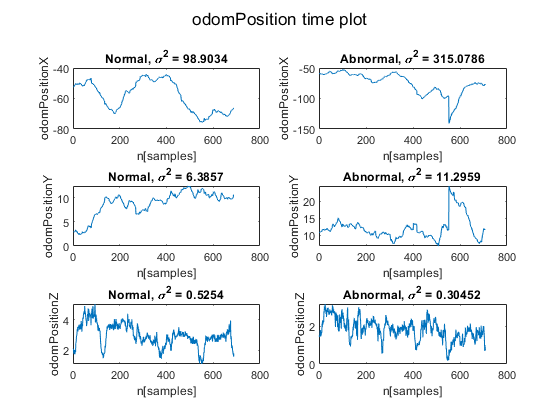

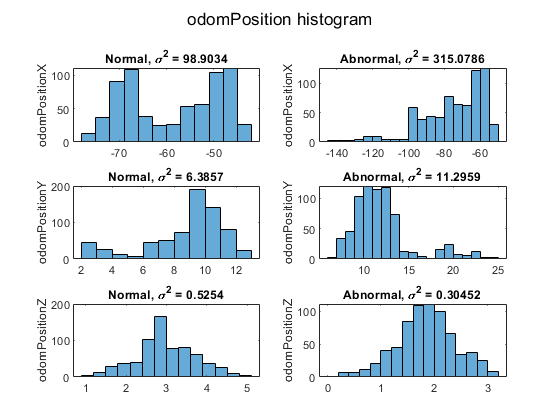

% close all
Vector3Suffixes = ["X" "Y" "Z"];
QuaternionSuffixes = ["X" "Y" "Z" "W"];

plotData(jointTableNormal, jointTableAbnormal, "odomPosition", Vector3Suffixes, figure(1), figure(2));

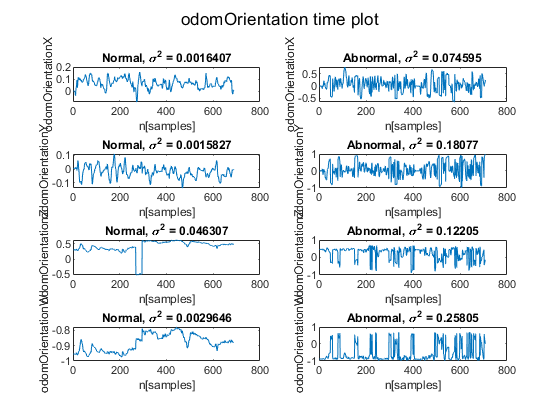

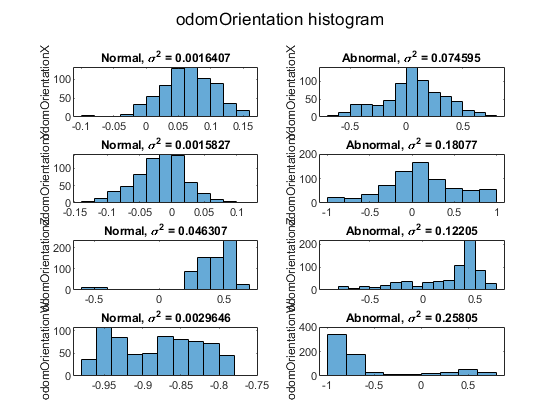

% doesn't look useful

plotData(jointTableNormal, jointTableAbnormal, "odomOrientation", QuaternionSuffixes, figure(3), figure(4));

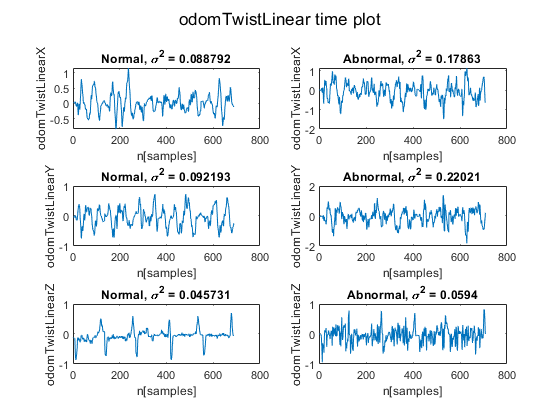

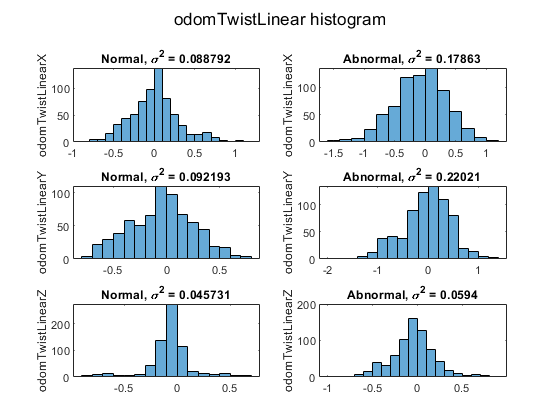

% high frequency oscillations on the abnormal data
% first derivative would be a very useful feature
% angular velocity? 

plotData(jointTableNormal, jointTableAbnormal, "odomTwistLinear", Vector3Suffixes, figure(5), figure(6));

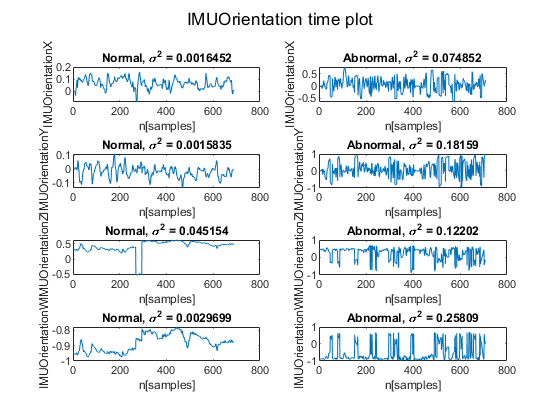

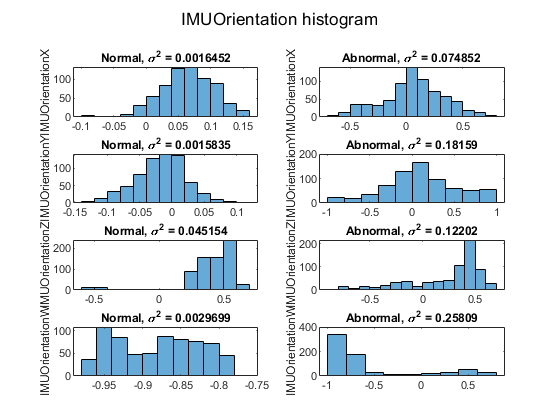

% looks like first derivative would be very useful
% linear acceleration?

plotData(jointTableNormal, jointTableAbnormal, "IMUOrientation", QuaternionSuffixes, figure(7), figure(8));

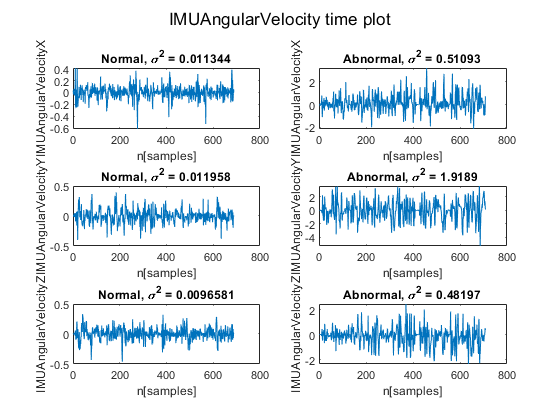

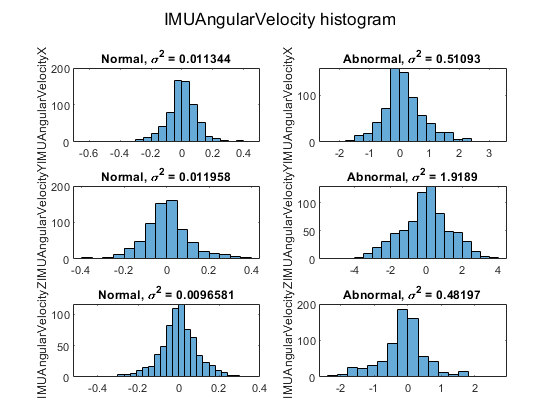

% this looks identical to odomOrientation

plotData(jointTableNormal, jointTableAbnormal, "IMUAngularVelocity", Vector3Suffixes, figure(9), figure(10));

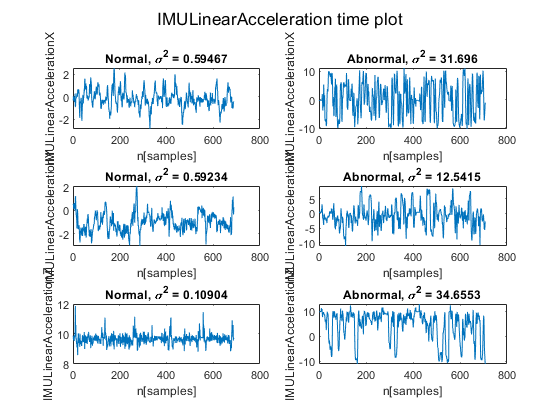

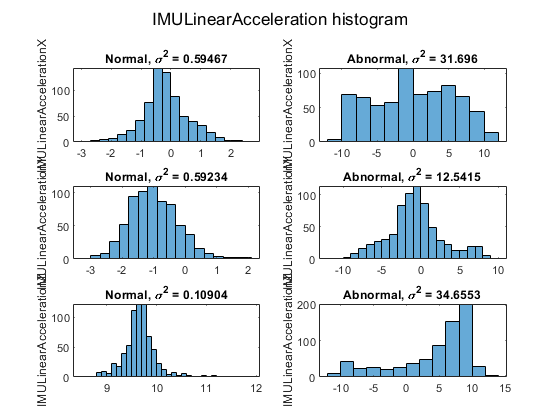

% just as anticipated, abnormals have much higher variance

plotData(jointTableNormal, jointTableAbnormal, "IMULinearAcceleration", Vector3Suffixes, figure(11), figure(12));

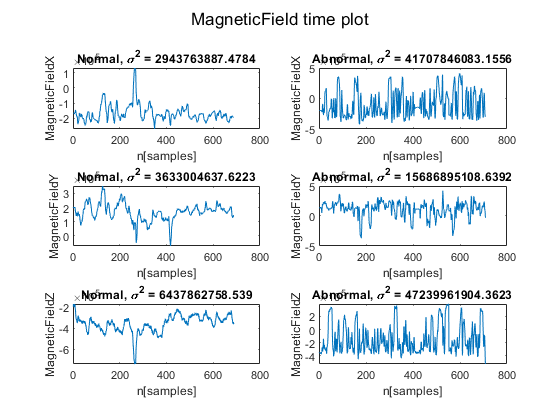

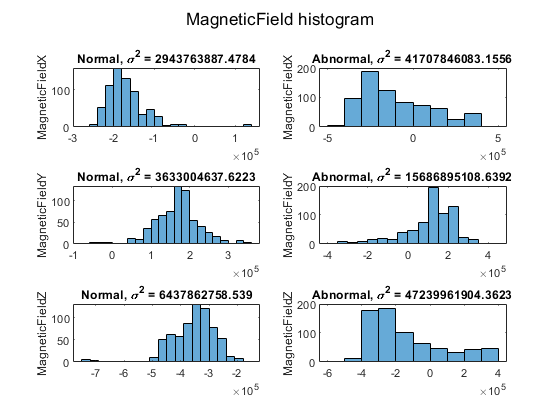

% just as anticipated, abnormals have much higher variance

plotData(jointTableNormal, jointTableAbnormal, "MagneticField", Vector3Suffixes, figure(13), figure(14));

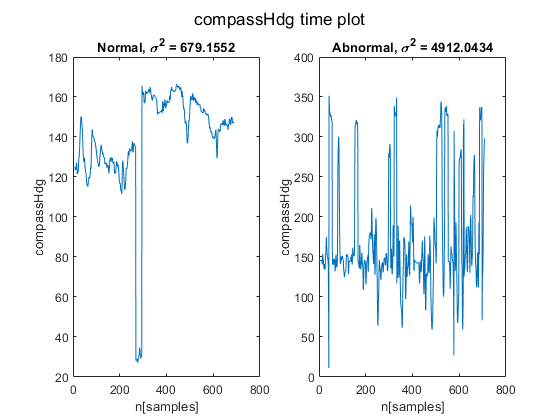

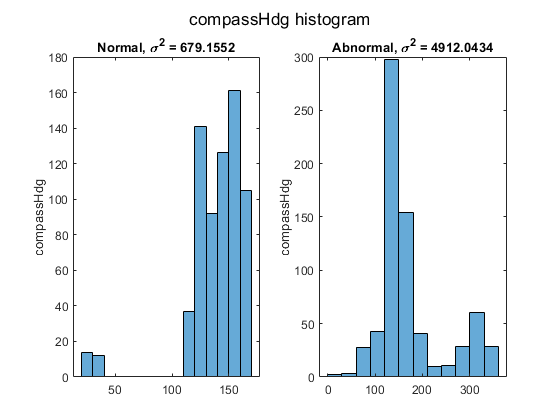

% high frequency oscillations on the abnormal data
% first derivative would be a useful feature

plotData(jointTableNormal, jointTableAbnormal, "compassHdg", "", figure(15), figure(16));

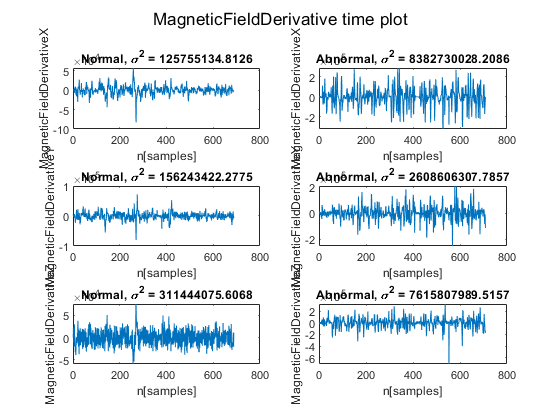

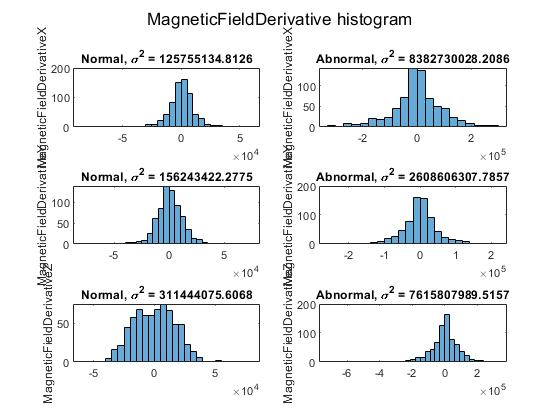

% high frequency oscillations on the abnormal data
% first derivative would be a useful feature

jointTableNormalAddDer = addDerivative(jointTableNormal, "MagneticField", Vector3Suffixes);
jointTableAbnormalAddDer = addDerivative(jointTableAbnormal, "MagneticField", Vector3Suffixes);

jointTableNormalAddDer = addDerivative(jointTableNormalAddDer, "compassHdg");
jointTableAbnormalAddDer = addDerivative(jointTableAbnormalAddDer, "compassHdg");

plotData(jointTableNormalAddDer, jointTableAbnormalAddDer, "MagneticFieldDerivative", Vector3Suffixes, figure(17), figure(18));

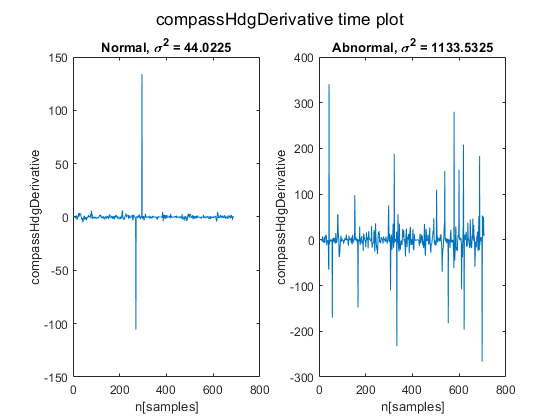

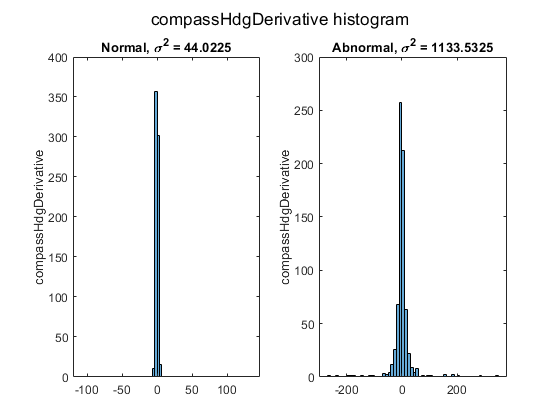

% just as anticipated, abnormals have much higher variance

plotData(jointTableNormalAddDer, jointTableAbnormalAddDer, "compassHdgDerivative", "", figure(19), figure(20));

% just as anticipated, abnormals have much higher variance

## 3. Klasifikacija

### Generisanje podataka za klasifikaciju

tableNormal = getFeatureTable(bagsNormal);
tableNormal = [tableNormal, table(zeros(5,1), 'VariableNames', "y")];
tableAbnormal = getFeatureTable(bagsAbnormal);
tableAbnormal = [tableAbnormal, table(ones(5,1), 'VariableNames', "y")];

tableXy = [tableNormal; tableAbnormal];

### Pokretanje Classification Learner aplikacije

classificationLearner

### Čuvanje modela

filenames = [
"modelEnsembleBaggedTrees",...
"modelKNNFine",...
"modelLinearDiscriminant",...
"modelLogisticRegression",...
"modelNaiveBayesGaussian",...
"modelSVMLinear"...
];
% save the models separately
for m = filenames
    save(m+".mat", m);
end
% save all objects with model in their names in one file
save models.mat -regexp 'model'